% clear
% close all
% clf

load EyesTestData.mat
load NotEyesTestData.mat
load EyesTrainData.mat
load NotEyesTrainData.mat

load cuvicSVM.mat

modelo = cubicSVM;

cell = [16 16];

image = EyesTestData(:, :, :, 1);
imageGray = rgb2gray(image);
hog = extractHOGFeatures(imageGray, 'CellSize', cell);

mida_eyes = size(EyesTestData);
test_data_eyes = zeros(mida_eyes(4), width(hog));
for i=1:mida_eyes(4)
    image = EyesTestData(:, :, :, i);
    imageGray = rgb2gray(image);
    test_data_eyes(i, :) = extractHOGFeatures(imageGray, 'CellSize', cell);
end

mida_not_eyes = size(NotEyesTestData);
test_data_not_eyes = zeros(mida_not_eyes(4), width(hog));
for i=1:mida_not_eyes(4)
    if (mod(i, 500) == 0)
        i
    end
    image = NotEyesTestData(:, :, :, i);
    imageGray = rgb2gray(image);
    test_data_not_eyes(i, :) = extractHOGFeatures(imageGray, 'CellSize', cell);
end

i = 500

i = 1000


test_data = [test_data_eyes, ones(mida_eyes(4), 1); test_data_not_eyes, zeros(mida_not_eyes(4), 1)];
T = array2table(test_data);

titulos = strings(width(hog), 1);
for i = 1: width(hog)
    titulos(i) = "Atr " + int2str(i);
end

titulos = [titulos; "Clase"];

T.Properties.VariableNames = titulos;

should = T.Clase;
yfit = modelo.predictFcn(T);

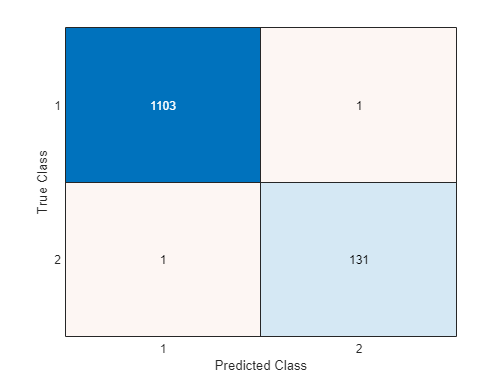

hola =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [1 2]

  Show all properties


hola = confusionchart(confusionmat(should, yfit))

image = EyesTrainData(:, :, :, 1);
imageGray = rgb2gray(image);
hog = extractHOGFeatures(imageGray, 'CellSize', cell);

mida_eyes = size(EyesTrainData);
train_data_eyes = zeros(mida_eyes(4), width(hog));
for i=1:mida_eyes(4)
    image = EyesTrainData(:, :, :, i);
    imageGray = rgb2gray(image);
    train_data_eyes(i, :) = extractHOGFeatures(imageGray, 'CellSize', cell);
end

mida_not_eyes = size(NotEyesTrainData);
train_data_not_eyes = zeros(mida_not_eyes(4), width(hog));
for i=1:mida_not_eyes(4)
    if (mod(i, 500) == 0)
        i
    end
    image = NotEyesTrainData(:, :, :, i);
    imageGray = rgb2gray(image);
    train_data_not_eyes(i, :) = extractHOGFeatures(imageGray, 'CellSize', cell);
end

i = 500

i = 1000

i = 1500

i = 2000

i = 2500

i = 3000

i = 3500

i = 4000

i = 4500

i = 5000

i = 5500

i = 6000

i = 6500

i = 7000

i = 7500

i = 8000

i = 8500

i = 9000

i = 9500

train_data = [train_data_eyes, ones(mida_eyes(4), 1); train_data_not_eyes, zeros(mida_not_eyes(4), 1)];
T = array2table(train_data);

titulos = strings(width(hog), 1);
for i = 1: width(hog)
    titulos(i) = "Atr " + int2str(i);
end

titulos = [titulos; "Clase"];

T.Properties.VariableNames = titulos;

should = T.Clase;
yfit = modelo.predictFcn(T);

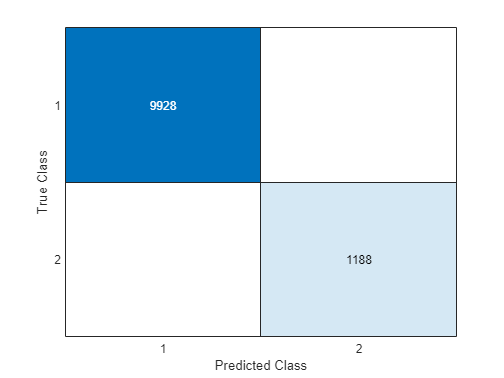

hola =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [1 2]

  Show all properties


hola = confusionchart(confusionmat(should, yfit))